clear
clf

data = readmatrix('04122023_ecoli.csv');
data_dim = size(data);
num_datapoints = data_dim(1);
addpath ../ % for access to fit_data function

% label data from csv
% exclude first data point
time = data(:, 1) / 60;     % hours

% 50%
A = data(:, 2); % optical density

% 60 %
B = data(:, 3); % optical density

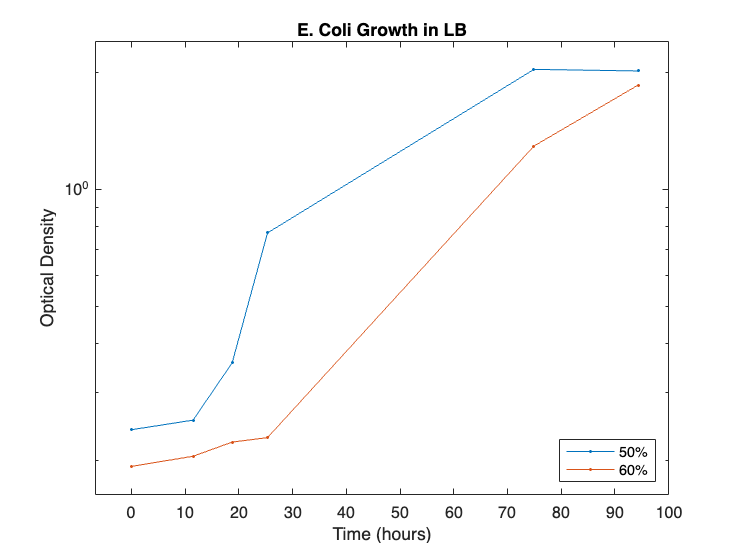

clf
semilogy(time, A, '.-');
hold on 
semilogy(time, B, '.-');

title("E. Coli Growth in LB")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("50%", "60%", "Location", "southeast")
axis padded

## Sample A

isolate_A = 2:4;
[fitA, gofA, growthrate_A, yieldA] = fit_data(A, isolate_A, time)

fitA =      General model Exp1:
     fitA(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.07012  (-0.3678, 0.5081)
       b =     0.09394  (-0.1718, 0.3597)

gofA = struct with fields:
           sse: 0.0051
       rsquare: 0.9658
           dfe: 1
    adjrsquare: 0.9317
          rmse: 0.0717


growthrate_A = 7.3785

yieldA = 1.7980

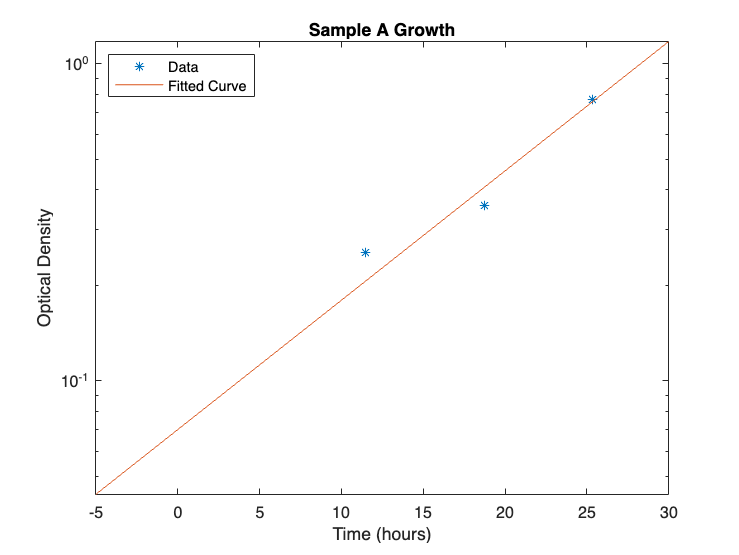

title("Sample A Growth")

## Sample B

isolate_B = 4:6;
[fitB, gofB, growthrate_B, yieldB] = fit_data(B, isolate_B, time)

fitB =      General model Exp1:
     fitB(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1816  (-1.016, 1.379)
       b =     0.02494  (-0.04959, 0.09947)

gofB = struct with fields:
           sse: 0.0289
       rsquare: 0.9789
           dfe: 1
    adjrsquare: 0.9577
          rmse: 0.1700


growthrate_B = 27.7964

yieldB = 1.6640

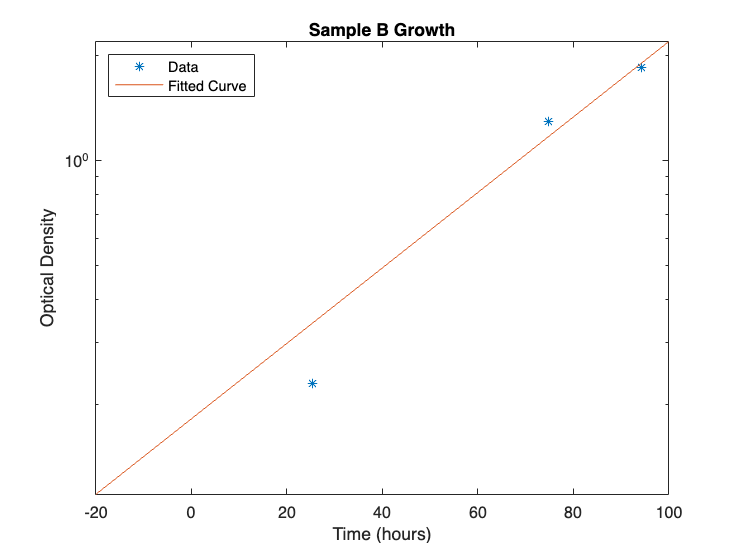

title("Sample B Growth")

## Growth Rates

growthrate_A

growthrate_A = 7.3785

growthrate_B

growthrate_B = 27.7964

## Yields

yieldA

yieldA = 1.7980

yieldB

yieldB = 1.6640